# **SEGMENTACIÓN SIN GROUND TRUTH**

clear all 
close all

% Para optimizarlo y que vaya más rápido
set(0, 'DefaultFigureVisible', 'off'); % Desactivar visualización de figuras
warning('off', 'images:imhistc:inputHasNaNs'); % Desactivar warnings no críticos

files = dir(); % Coger todos los archivos
imageExtensions = {'.jpg', '.tiff'};
imageFiles = {};

for k = 1:length(files)
    [~, ~, ext] = fileparts(files(k).name);
    if ismember(lower(ext), imageExtensions)
        imageFiles{end+1} = files(k).name;
    end
end

columnas = {
    'ImageName','GlobulosBlancosDetectados', 'ParasitosDetectados', ... 
    'Leu_median_Area', 'Leu_median_BoundingBox','Leu_median_Eccentricity','Leu_median_Circularity','Leu_median_Diameter','Leu_median_Solidity','Leu_median_Perimeter','Leu_median_Intensity' ... 
    'Par_median_Area', 'Par_median_BoundingBox','Par_median_Eccentricity','Par_median_Circularity','Par_median_Diameter','Par_median_Solidity','Par_median_Perimeter','Par_median_Intensity'
};

Tabla_Global = table(...
    'Size', [0, numel(columnas)], ...
    'VariableTypes', [{'string'}, repmat({'double'}, 1, numel(columnas)-1)], ...
    'VariableNames', columnas ...
);

Procesado de cada imagen:


Procesando imagen 1 de 16: 20170724_144112.jpg


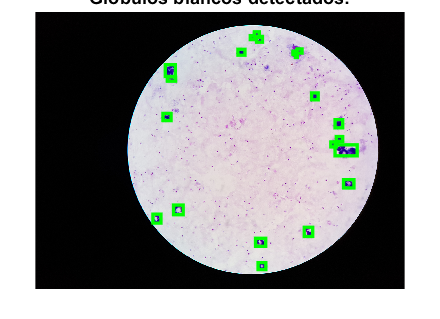

globulos_blancos_detectados = '21'

num_parasitos = 43

num_parasitos = 43

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.6259    0.9529
    1.7524    1.8379
    1.8048    0.7453
    1.9377    2.3742
    1.9587    2.2544
    2.0068    1.3591
    2.0181    1.3496
    2.0741    1.4293
    2.1430    0.7556
    2.1662    0.5692


radios =     5.8632    5.2624    7.6113    5.1090    5.1709    5.1400    5.5852    5.9441    5.7259    5.9708    5.4115    6.4820    5.3226    5.3820    5.6700    5.4700    5.1709    5.6700    5.8632    6.2825    5.0777    5.3226    5.4115    5.2624    5.2624    5.3820    5.8903    5.5566    6.7703    9.9496    5.5279    6.2317    5.3820    6.2572    6.8868    6.3581    5.2321    5.6136    5.7259    5.1090    5.1090    5.4408    5.3820



Procesando imagen 2 de 16: 20170724_144325.jpg


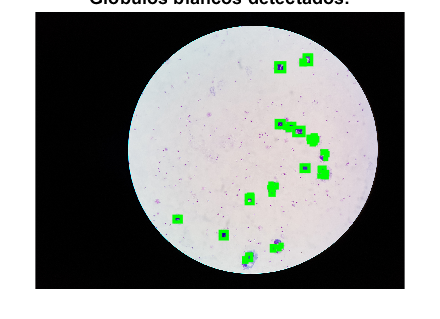

globulos_blancos_detectados = '39'

num_parasitos = 2

num_parasitos = 2

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    2.5953    1.9354
    2.6319    2.5653


radios =    11.5073    6.9329



Procesando imagen 3 de 16: 20170724_144553.jpg


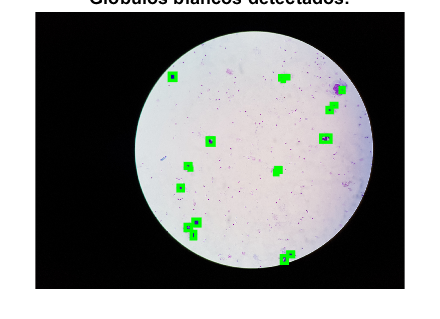

globulos_blancos_detectados = '19'

num_parasitos = 11

num_parasitos = 11

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    3.0244    2.2549
    3.1141    1.6488
    3.2817    1.5393
    3.3155    1.7744
    3.3175    1.4734
    3.3720    1.7755
    3.3843    1.0349
    3.4329    1.8485
    3.4827    1.6522
    3.5439    1.2305


radios =     5.2624    5.4990    7.8987    7.3561    6.3078    5.6980    5.5852    6.0503    8.1369    6.0239    5.2016



Procesando imagen 4 de 16: 20170724_144756.jpg


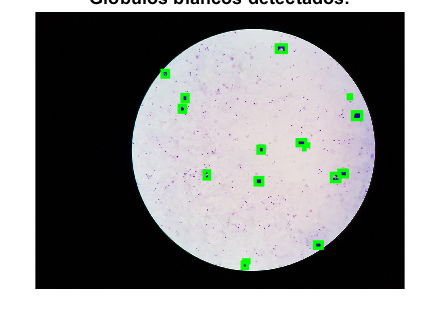

globulos_blancos_detectados = '17'

num_parasitos = 9

num_parasitos = 9

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.7825    1.9902
    1.8800    1.5463
    2.9361    1.4949
    3.1047    1.7177
    3.1122    1.2936
    3.3202    1.4329
    3.3760    1.4083
    3.4241    1.4372
    3.6099    1.9560


radios =     6.1287    5.1090    8.5191    5.2016    5.6136    5.6700    5.4408    5.9708    6.9099



Procesando imagen 5 de 16: 20170724_144941.jpg


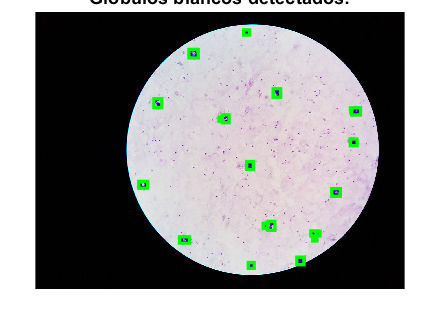

globulos_blancos_detectados = '20'

num_parasitos = 19

num_parasitos = 19

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.3558    1.4048
    1.6110    1.4605
    2.0936    0.8036
    2.2149    2.4650
    2.3441    1.2768
    2.4875    1.2237
    2.6266    1.2634
    2.7045    1.6574
    2.7443    1.2955
    2.7797    1.8164


radios =     5.1090    5.1090    5.6136    5.2321    5.2926    5.7259    5.7536    6.0503    5.4408    5.3226    5.3226    5.1090    5.9441    5.3226    5.4700    5.8087    6.4080    9.9336    5.3820



Procesando imagen 6 de 16: 20170724_145215.jpg


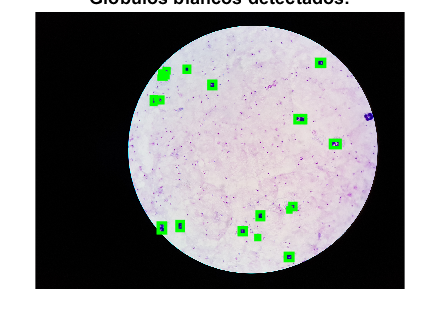

globulos_blancos_detectados = '20'

num_parasitos = 34

num_parasitos = 34

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.5469    1.5582
    1.5765    1.8311
    1.6454    1.6082
    1.6953    1.4266
    1.8408    1.9473
    2.0288    2.0294
    2.0915    2.0790
    2.1146    1.5270
    2.2515    1.1049
    2.3177    2.3536


radios =     5.6700    5.3820    5.6419    5.2016    5.2016    5.1090    5.6419    5.2016    5.5279    5.0777    6.1287    5.0777    7.2031    5.1709    5.1090    5.1709    6.1026    5.1709    6.8171    6.0765    5.8087    5.7259    6.6756    5.2926    5.2016    5.4990    5.2016    6.1546    6.2061    5.6136    6.2825    5.4115    5.2321    5.2321



Procesando imagen 7 de 16: 20170724_145437.jpg


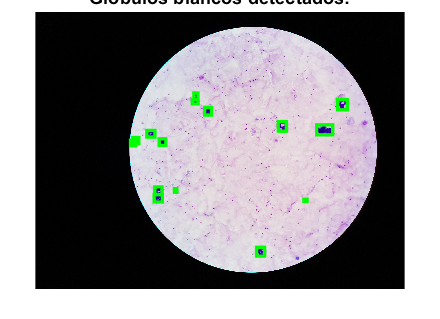

globulos_blancos_detectados = '15'

num_parasitos = 73

num_parasitos = 73

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.3255    0.9734
    1.4874    1.5626
    1.5850    1.6923
    1.5880    1.5050
    1.6427    1.3043
    1.6504    0.9569
    1.6744    1.3291
    1.7673    0.7196
    1.8239    1.6158
    1.8537    0.6714


radios =     5.2926    5.2321    5.2926    5.3524    5.9708    7.3345    5.6136    6.2825    5.4115    5.5566    6.0503    6.3078    5.5852    6.7703    5.2624    5.5279    5.1400    5.2321    5.5852    7.1365    6.3078    5.1400    7.0014    5.5852    8.7948    5.9441    5.5852    5.4115    6.2572    6.2825    5.4700    8.0186    5.5566    5.2624    5.6136    6.1287    5.4115    6.1287    5.3524    5.8632    5.8360    5.6980    5.1090    7.0014    5.5852    5.2624    5.0777    5.5852    8.0186    5.6700



Procesando imagen 8 de 16: 20170724_145603.jpg


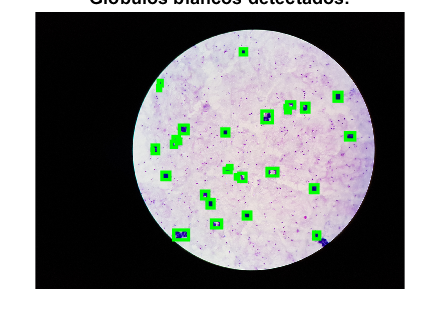

globulos_blancos_detectados = '30'

num_parasitos = 71

num_parasitos = 71

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.3235    0.9210
    1.3505    1.0142
    1.6381    0.8000
    1.7659    1.8729
    1.8013    1.3384
    1.8454    0.9041
    1.8703    1.6522
    1.8731    0.9776
    2.0013    0.5871
    2.0354    1.6362


radios =     5.4990    5.2016    5.4990    7.6738    5.2926    5.4700    5.1090    6.4328    5.3524    5.4990    6.2572    5.0777    6.8404    5.8360    5.8087    5.1400    5.8903    5.2926    6.9786    5.4990    5.6419    5.2321    5.0777    5.7812    5.9441    5.4700    5.6136    6.0239    5.2624    5.3226    5.3524    6.0503    5.6700    5.8360    5.1090    6.5310    7.0693    5.9441    5.6419    5.4990    5.7259    7.5904    5.1400    6.2825    6.4820    5.4700   12.9026    6.8637    6.5310    6.0239



Procesando imagen 9 de 16: 20170724_145730.jpg


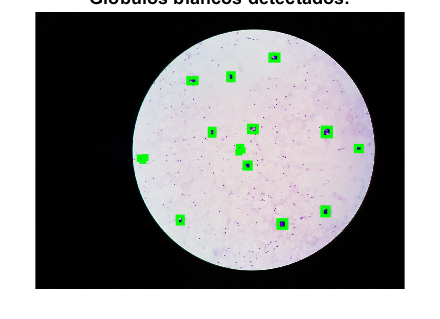

globulos_blancos_detectados = '17'

num_parasitos = 12

num_parasitos = 12

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    2.0120    2.1784
    2.4025    1.3367
    2.6203    2.1428
    2.6251    1.4400
    2.7340    1.0704
    2.8117    2.4317
    2.8154    1.4080
    2.8672    1.9692
    2.9489    1.1354
    3.3175    1.5024


radios =     5.0777    5.4990    5.2624    5.2321    5.4408    5.8360    5.4115    5.6419    5.6700    6.4820    5.3226    5.2321



Procesando imagen 10 de 16: 20170724_145845.jpg


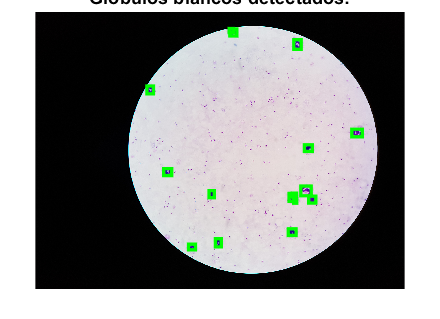

globulos_blancos_detectados = '16'

num_parasitos = 4

num_parasitos = 4

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.8498    1.0301
    1.9088    1.3545
    2.5925    2.2195
    2.8187    0.9480


radios =     5.3226    5.2624    5.3820    5.2624



Procesando imagen 11 de 16: 20170724_150155.jpg


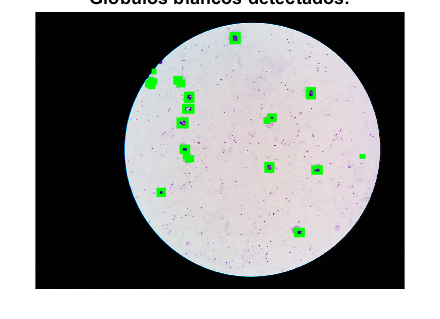

globulos_blancos_detectados = '24'

num_parasitos = 3

num_parasitos = 3

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.7852    1.4292
    2.0322    0.7377
    2.2466    2.4282


radios =     9.3730    5.1400    5.2016



Procesando imagen 12 de 16: 20170724_150436.jpg


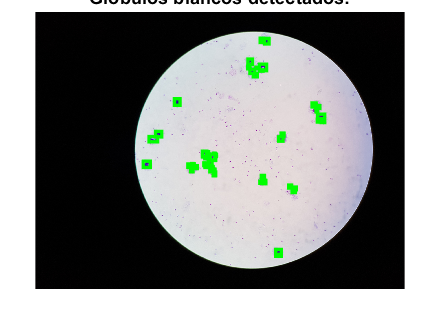

globulos_blancos_detectados = '46'

num_parasitos = 2

num_parasitos = 2

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.9494    1.7267
    3.2270    1.8192


radios =    13.2434    5.4990



Procesando imagen 13 de 16: 20170724_150706.jpg


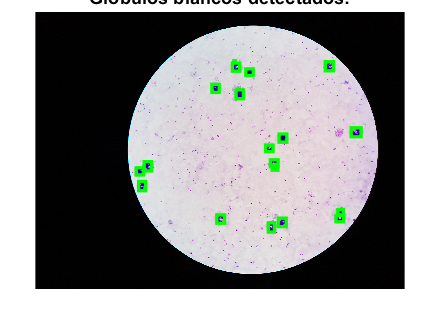

globulos_blancos_detectados = '19'

num_parasitos = 22

num_parasitos = 22

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.7018    2.6364
    2.1750    0.5408
    2.2265    1.6705
    2.3011    2.2783
    2.3330    1.9173
    2.4794    2.3672
    2.5080    1.2094
    2.5155    2.1495
    2.5550    1.6777
    2.5953    2.2722


radios =     5.2926   10.0609    6.6037    5.3524    5.4700    5.6980    5.1709    5.2624    5.4990    5.3226    5.5279    7.0241    5.6419    5.8360    5.3820    5.1709    5.2016    5.6136    5.1709    5.2926    5.7259    5.8360



Procesando imagen 14 de 16: 20170724_150834.jpg


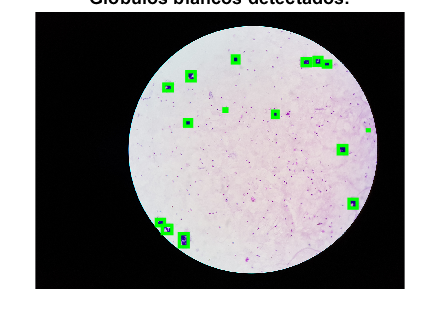

globulos_blancos_detectados = '15'

num_parasitos = 25

num_parasitos = 25

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    2.4539    1.8415
    2.5625    1.9233
    2.6302    1.3394
    2.6600    1.5853
    2.6852    1.1447
    2.7192    2.0539
    2.7695    1.6330
    2.7755    1.7253
    2.7781    1.0862
    2.7834    2.0414


radios =     5.6700    5.1709    6.4328    5.1709    5.0777    5.2016    5.7536    5.1400    6.1287    5.2016    5.3524    5.2926    5.8087    5.2016    6.5795    6.9099    5.6419    5.6136    7.1142    5.2926    5.3524    5.5279    5.5566    5.3524   10.0767



Procesando imagen 15 de 16: 20170724_151053.jpg


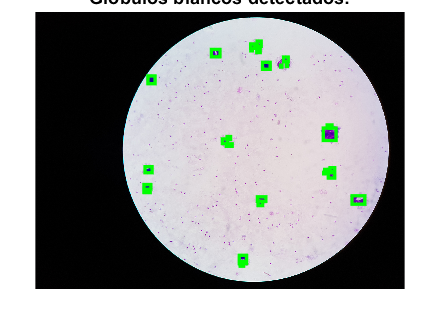

globulos_blancos_detectados = '30'

num_parasitos = 8

num_parasitos = 8

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.6064    2.2941
    1.7354    2.5868
    1.8151    2.3848
    1.8744    2.4046
    1.8875    2.1429
    2.0672    2.5182
    2.3558    2.5427
    3.3004    1.3708


radios =     5.0777    5.0777    5.6700    6.0503    5.1400    5.1709    5.3820    5.1090



Procesando imagen 16 de 16: 20170724_151215.jpg


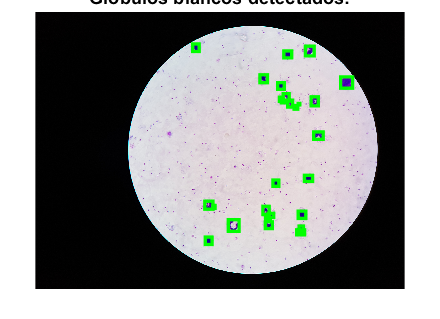

globulos_blancos_detectados = '27'

num_parasitos = 3

num_parasitos = 3

mask_parasitos = 3024×4032 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

centros = 1.0e+03 *

    1.8600    1.4321
    2.7410    0.8678
    2.8774    0.9856


radios =     5.1400    5.2926    6.3581


for imgIdx = 1:length(imageFiles)
    I = imread(imageFiles{imgIdx});

    fprintf('\nProcesando imagen %d de %d: %s\n', imgIdx, length(imageFiles), imageFiles{imgIdx});

    % ============ 1. CONVERTIR A ESCALA DE GRISES ============ %
    [alto, ancho] = size(I);
    I_double = im2double(I);
    I_gris = rgb2gray(I);
    I_gris_double = im2double(I_gris);


    % ============ 2. APLICAR FILTROS ============ %
    I_Gauss = imgaussfilt(I_double);
    I_Gauss_double = im2double(I_Gauss);

    
    % ============ 3. OTSU ============ %
    A = mean(im2double(I_Gauss), 3); % Promedia los 3 canales RGB --> transforma a grises
    TO = graythresh(A);
    C = A > TO;

    % 3.1. Glóbulos Blancos
    BW_invert = ~C; % Invierte la imagen (blanco a negro y negro a blanco)
    BW_clean = bwareaopen(BW_invert, 50); % Quita ruido pequeño (con menos de 50 pixeles)
    [L, num] = bwlabel(BW_clean); % Etiqueta los objetos conectados = se identifican las zonas grandes
    
    stats = regionprops(L, 'Area', 'Centroid', 'BoundingBox');
    min_area = 100;
    max_area = 30000;
    mask_filtered = false(size(BW_clean));
    
    for k = 1:num
        if stats(k).Area > min_area && stats(k).Area < max_area
            mask_filtered(L == k) = true;
        end
    end % Nos quedamos con las formas que tienen un tamaño razoable = glóbulos blancos
    
    [L_filtered, num_filtered] = bwlabel(mask_filtered);
    stats_filtered = regionprops(L_filtered, 'Area', 'Centroid', 'BoundingBox');

    figure;
    imshow(I_Gauss); hold on;
    for k = 1:num_filtered
        rectangle('Position', stats_filtered(k).BoundingBox,'EdgeColor','g','LineWidth',2);
    end
    hold off;
    title(['Globulos blancos detectados:']);
    globulos_blancos_detectados = num2str(num_filtered)

    % 3.2. Parásitos
    [num_parasitos, mask_parasitos, centros, radios] = detectarParasitos(I_Gauss)
    

    % ============ 4. GUARDAR CARACTERÍSTICAS ============ %
    stats_filtered_leu = regionprops(mask_filtered, I_gris_double, ...
    'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', ...
    'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
    if ~isempty(stats_filtered_leu)
        Globulos_Blancos_Caracteristicas = struct2table(stats_filtered_leu);
    else
        Globulos_Blancos_Caracteristicas = table();
    end

    stats_filtered_par = regionprops(mask_parasitos, I_gris_double, ...
    'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', ...
    'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
    if ~isempty(stats_filtered_par)
        Parasitos_Caracteristicas = struct2table(stats_filtered_par);
    else
        Parasitos_Caracteristicas = table();
    end

    nueva_fila = table(...
        string(imageFiles{imgIdx}), NaN, NaN, ...
        NaN, NaN, NaN, NaN, NaN, NaN, NaN, NaN, ...
        NaN, NaN, NaN, NaN, NaN, NaN, NaN, NaN, ...
        'VariableNames', columnas);
    nueva_fila.GlobulosBlancosDetectados = num_filtered;
    nueva_fila.ParasitosDetectados = num_parasitos;


    % 4.1. Glóbulos Blancos
    if ~isempty(stats_filtered_leu)
        nueva_fila.Leu_median_Area = median([stats_filtered_leu.Area]);
        nueva_fila.Leu_median_BoundingBox = mean(median([stats_filtered_leu.BoundingBox]));
        nueva_fila.Leu_median_Eccentricity = median([stats_filtered_leu.Eccentricity]);
        nueva_fila.Leu_median_Circularity = median([stats_filtered_leu.Circularity]);
        nueva_fila.Leu_median_Diameter = median([stats_filtered_leu.EquivDiameter]);
        nueva_fila.Leu_median_Solidity = median([stats_filtered_leu.Solidity]);
        nueva_fila.Leu_median_Perimeter = median([stats_filtered_leu.Perimeter]);
        nueva_fila.Leu_median_Intensity = median([stats_filtered_leu.MeanIntensity]);
    else
        nueva_fila{:, 4:11} = NaN;
    end
    
    % 4.2. Parásitos
    if ~isempty(stats_filtered_par)
        nueva_fila.Par_median_Area = median([stats_filtered_par.Area]);
        nueva_fila.Par_median_BoundingBox = mean(median([stats_filtered_par.BoundingBox]));
        nueva_fila.Par_median_Eccentricity = median([stats_filtered_par.Eccentricity]);
        nueva_fila.Par_median_Circularity = median([stats_filtered_par.Circularity]);
        nueva_fila.Par_median_Diameter = median([stats_filtered_par.EquivDiameter]);
        nueva_fila.Par_median_Solidity = median([stats_filtered_par.Solidity]);
        nueva_fila.Par_median_Perimeter = median([stats_filtered_par.Perimeter]);
        nueva_fila.Par_median_Intensity = median([stats_filtered_par.MeanIntensity]);
    else
        nueva_fila{:, 12:end} = NaN;
    end
    Tabla_Global = [Tabla_Global; nueva_fila];
end


% ============ ELIMINAR POSIBLES DUPLICADOS (POR SI ACASO) ============ %
[~, idx] = unique(Tabla_Global.ImageName, 'stable');
Tabla_Global = Tabla_Global(idx,:);

writetable(Tabla_Global, 'Falciparum_Data.csv');

fprintf('\nProcesamiento completado para todas las imágenes.\n');


Procesamiento completado para todas las imágenes.


display(Tabla_Global);

Tabla_Global = 16×19 table
          ImageName          GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity
    _____________________    _________________________    ___________________    _______________    ____________

% 3.2. Parásitos
function [num_parasitos, mask_parasitos, centros, radios] = detectarParasitos(I_sin_globulos)
    % Convertir a escala de grises y mejorar contraste
    I_gray = rgb2gray(I_sin_globulos);
    I_contrast = adapthisteq(I_gray);
    th = graythresh(I_contrast);
    BW = imbinarize(I_contrast, th);
    BW = imopen(~BW, strel('disk', 1));
    BW_clean = bwareaopen(BW, 10);

    % Etiquetar y extraer características
    [L, num] = bwlabel(BW_clean);
    stats = regionprops(L, 'Area', 'Centroid', 'EquivDiameter', ...
                           'Eccentricity', 'Solidity', 'Perimeter', 'BoundingBox');

    mask_parasitos = false(size(BW_clean));

    for k = 1:num
        area = stats(k).Area;
        ecc = stats(k).Eccentricity;
        sol = stats(k).Solidity;
        peri = stats(k).Perimeter;
        bbox = stats(k).BoundingBox;

        % Circularidad: 1 = perfecto círculo
        circ = 0;
        if peri > 0
            circ = 4 * pi * area / (peri^2);
        end

        % Aspect ratio del bounding box
        aspect_ratio = bbox(3) / bbox(4); % ancho / alto

        % Filtro basado en características morfológicas
        if area > 80 && area < 600 && ...
           ecc < 0.9 && sol > 0.85 && ...
           circ > 0.6 && aspect_ratio > 0.9 && aspect_ratio < 1.35
            mask_parasitos(L == k) = true;
        end
    end

    [~, num_parasitos] = bwlabel(mask_parasitos);
    num_parasitos
    stats_filtered = regionprops(mask_parasitos, 'Centroid', 'EquivDiameter');
    centros = cat(1, stats_filtered.Centroid);
    radios = [stats_filtered.EquivDiameter] / 2;
end